save_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\';

surf_file = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\mni152_FSL\surf\lh.white';
[VinnL_raw,F] = read_surf(surf_file); V = VinnL_raw;
surf_file = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\mni152_FSL\surf\lh.pial';
[VoutL_raw,F] = read_surf(surf_file); VmidL_raw = (VinnL_raw+VoutL_raw)/2;

V = V + mni_gray.shape/2;
VinnL_raw = VinnL_raw + mni_gray.shape/2;
VmidL_raw = VmidL_raw + mni_gray.shape/2;
VoutL_raw = VoutL_raw + mni_gray.shape/2;
size(V,1)

ans =       156277


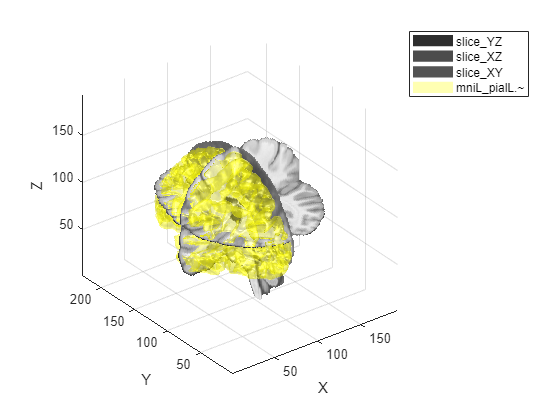

F = F+1;

% surf_file = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00004\surf\T1_reg.DL.right.inner.ply';
% surf_ply = Surf_read_Data(surf_file); V = surf_ply.Vertices; F = surf_ply.Faces;
% 
mniL_pialL = struct('Vertices',V,'Faces',F);

figure; colormap gray
next; slice_mri(mni_gray); hold on; plot_surf(mniL_pialL,'colors',[1,1,0],'alphas',0.3)

tic
temp = mniL_pialL;
temp = Surf_func_ROI(mniL_pialL,'reduce',2);
mniL_pialL_bin2 = Surf_remesh(temp,'len',1.8); % 1.8
size(mniL_pialL_bin2.Vertices,1)

ans =        42315


size(mniL_pialL_bin2.Vertices,1)*2 - size(mniL_pialL_bin2.Faces,1)

ans =      4


toc

历时 20.629481 秒。


# white FSL annoation

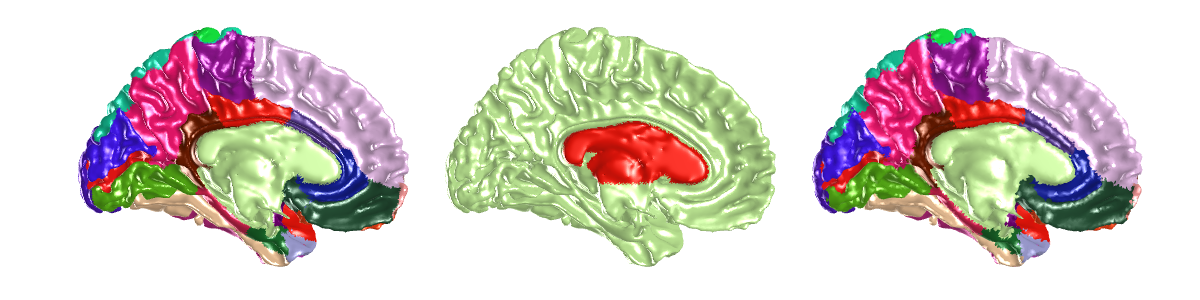

[vertices, label, colortable] = read_annotation('E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\mni152_FSL\label\lh.aparc.annot');
[label_uniq,~,label_re] = unique(label);
cmap_raw = colortable.table;
[~,idxL] = ismember(cmap_raw(:,5),label_uniq);
idxL(idxL==0) = [];
cmap_FSLre = cmap_raw(idxL,1:3)/255;

vidxL_iswhite = label_re==1 & mniL_pialL.Vertices(:,1)>90 & mniL_pialL.Vertices(:,3)>75;

[vidxL_match] = knnsearch(mniL_pialL.Vertices,mniL_pialL_bin2.Vertices);
Labels_FSL = label_re(vidxL_match);
mniL_pialL_bin2.Labels_FSL = Labels_FSL;
mniL_pialL_bin2.cmap_FSLre = cmap_FSLre;
mniL_pialL_bin2.vidxL_match = vidxL_match;

save('E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\cmap_FSLre.mat','cmap_FSLre','Labels_FSL','colortable')

figure; lay_sub(1,3)
next; plot_surf(mniL_pialL,'colors',label_re); next; plot_surf(mniL_pialL,'colors',double(vidxL_iswhite))
next; plot_surf(mniL_pialL_bin2,'colors',mniL_pialL_bin2.Labels_FSL);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(90,0); colormap(cmap_FSLre)

# BST label

mniL_pialL_bin2.VinnL = VinnL_raw(vidxL_match,:);
mniL_pialL_bin2.VmidL = VmidL_raw(vidxL_match,:);
mniL_pialL_bin2.VoutL = VoutL_raw(vidxL_match,:);
mniL_pialL_bin2.Labels_BST = MRI_func_ROI(mni_atlas,'sample','pos',mniL_pialL_bin2.VmidL,'method',0);

Surf_save_File(mniL_pialL_bin2,[save_dir,'mniL_pialL_bin2.~']);

    1: E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\mniL_pialL_bin2.~    



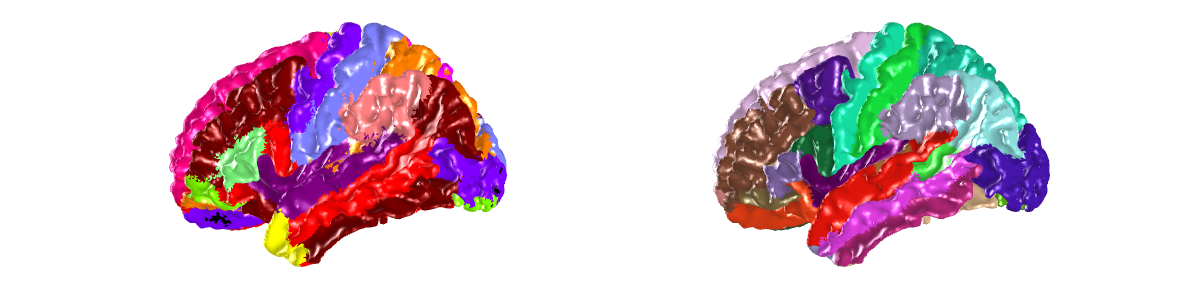


figure;
next; colormapa(atlas_cmap); plot_surf(mniL_pialL_bin2,'colors',mniL_pialL_bin2.Labels_BST); caxis([0 size(atlas_cmap,1)])
next; colormapa(cmap_FSLre); plot_surf(mniL_pialL_bin2,'colors',mniL_pialL_bin2.Labels_FSL);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(-90,0)

# surface 3D registration

tic
[mniL_sm3_rd, idxL_rd1] = Surf_func_ROI(mniL_sm3,'reduce','bin',8,'get_idx',1);
[subjL_sm3_rd, idxL_rd2] = Surf_func_ROI(subjL_sm3,'reduce','bin',8,'get_idx',1);

[surf_reg_rd,rotVecs] = Surf_warp(subjL_sm3_rd,mniL_sm3_rd,'pointcloud_reg_icp','pc_para',{'Metric','pointToPlane'}); % must use pointToPlane !
[surf_reg_rd] = Surf_warp(surf_reg_rd,mniL_sm3_rd,'pointcloud_reg_cpd','norm_init',0, ...
         'param',{'MaxIterations',30,'OutlierRatio',0.1,'InteractionSigma',0.1,'SmoothingWeight',0.1}); % 1e-4 for fast, 4s
toc

历时 38.041327 秒。


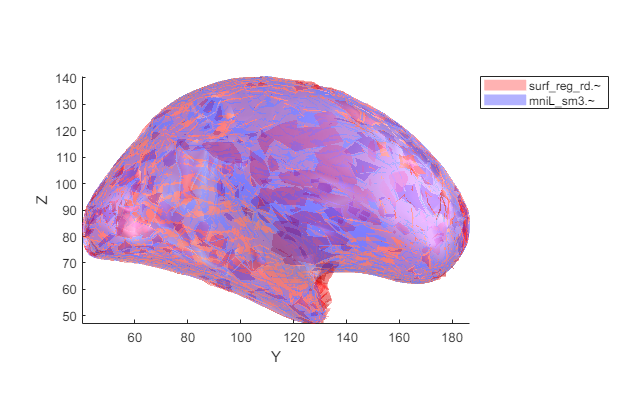


figure;
next; plot_surf(surf_reg_rd,'colors',[1,0,0],'alphas',0.3)
hold on; plot_surf(mniL_sm3,'colors',[0,0,1],'alphas',0.3)
view(90,0)

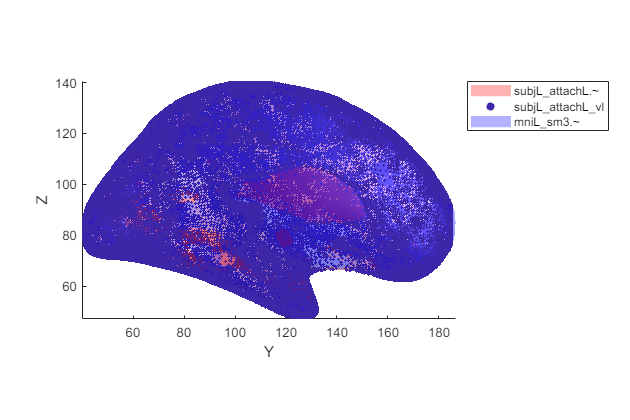

surf_reg = subjL_sm3;
surf_reg.Vertices = interp_sph(subjL_sph.Vertices(idxL_rd2,:),surf_reg_rd.Vertices,subjL_sph.Vertices);
subjL_attachL = surf_reg;

for i = 1:5
    [subjL_attachL] = Surf_smooth(subjL_attachL,'iter',10,'type',3);
    subjL_attachL.Vertices = Surf_func_ROI(mniL_sm3,'attach','pos',subjL_attachL.Vertices);
end
[subjL_attachL] = Surf_smooth(subjL_attachL,'iter',3,'type',3);

figure;
next; plot_surf(subjL_attachL,'colors',[1,0,0],'alphas',0.3,'show_vl',1)
hold on; plot_surf(mniL_sm3,'colors',[0,0,1],'alphas',0.3)
view(90,0)

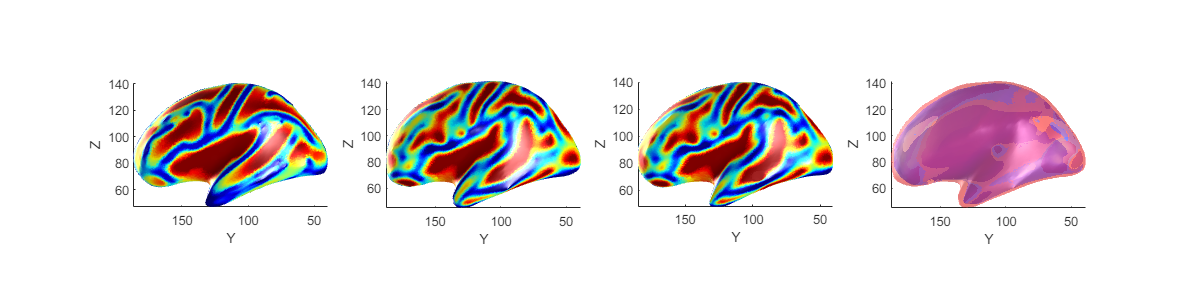

figure; colormap jet
next; plot_surf(mniL_sm3,'colors',mniLK3);
next; plot_surf(subjL_sm3,'colors',subjLK3);
next; plot_surf(subjL_attachL,'colors',subjLK3);
next; plot_surf(subjL_sm3,'colors',[1,0,0],'alphas',0.3); hold on; plot_surf(subjL_attachL,'colors',[0,0,1],'alphas',0.3)
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view'); view(-90,0)

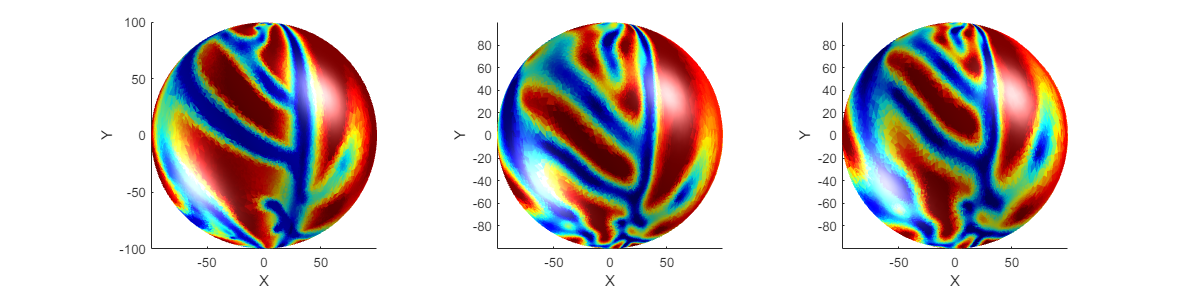

Vat = subjL_attachL.Vertices; VmniL = mniL_sm3.Vertices;
idxL_mniL2subjL = knnsearch(Vat,VmniL);
idxL_subjL2mniL = knnsearch(VmniL,Vat);

subjL_sphreg = subjL_sph; subjL_sphreg.Vertices = mniL_sph.Vertices(idxL_subjL2mniL,:);
[subjL_sphreg] = Surf_smooth(subjL_sphreg,'iter',3,'type',3);
subjL_sphreg.Vertices = subjL_sphreg.Vertices./vecnorm(subjL_sphreg.Vertices,2,2)*SD_atlas.radius;

figure; colormap jet
next; plot_surf(mniL_sph,'colors',mniLK3);
next; plot_surf(subjL_sph,'colors',subjLK3);
next; plot_surf(subjL_sphreg,'colors',subjLK3);
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view');

save([save_dir,'subjL_sphreg.mat'],'subjL_attachL','mniL_sm3','idxL_mniL2subjL','idxL_subjL2mniL','subjL_sphreg','subjL_file','subjL_sm3','sm_iters')

# revise white hole

Reading from version 2
colortable with 36 entries read (originally /autofs/space/tanha_002/users/greve/fsdev.build/average/colortable_desikan_killiany.txt)


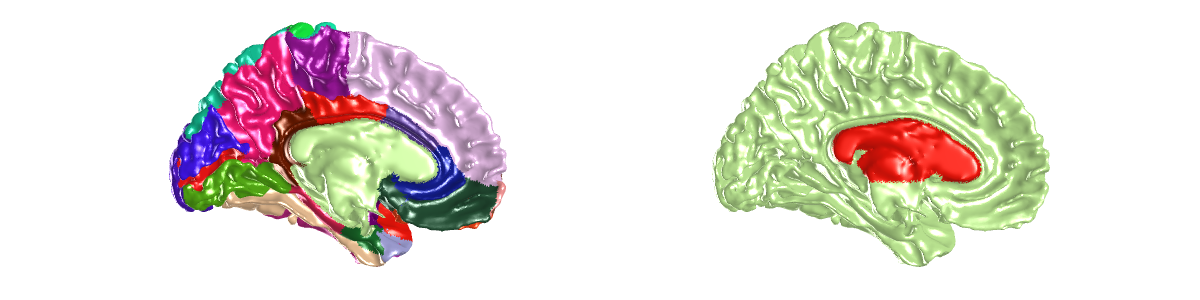

surf_in = mniL_pialL_bin2;

temp = knnsearch(surf_in.Vertices,mniL_pialL.Vertices(vidxL_iswhite,:));
vbinidxL_iswhite = zeros(size(surf_in.Vertices,1),1); vbinidxL_iswhite(temp) = 1;

surf_in.Labels = vbinidxL_iswhite;
tic
for i = 1:2
    evalc("surf_in = Surf_func_filt(surf_in,'V',@median);");
    surf_in.Labels = round(surf_in.Labels);
end
toc

历时 5.620967 秒。


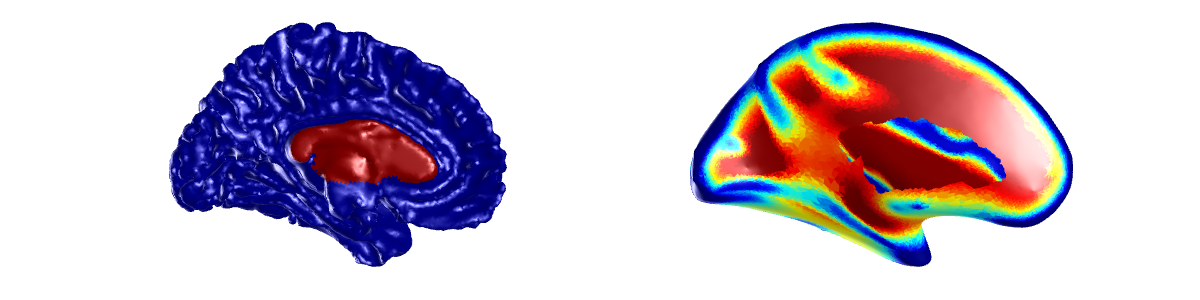

vbinidxL_iswhite = surf_in.Labels;

surf_in = mniL_sm3;
[surf_mniLdiv,~,idxL] = Surf_func_ROI(surf_in,'divide',vbinidxL_iswhite==0);
val = mniLK3(idxL{2});

figure;
next; plot_surf(mniL_pialL_bin2,'colors',vbinidxL_iswhite)
next; plot_surf(surf_mniLdiv{2},'colors',val);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(90,0); colormap jet

temp = Surf_func_ROI(mniL_sm3,'divide',vbinidxL_iswhite>0);
surf_white = Surf_func_ROI(temp{2},'refine',2);
temp = knnsearch(subjL_attachL.Vertices,surf_white.Vertices);
vregidxL_iswhite = zeros(size(subjL_attachL.Vertices,1),1); vregidxL_iswhite(temp) = 1;

surf_in = subjL_attachL;
v = surf_in.Vertices;
vregidxL_iswhite(v(:,2)<105 & v(:,3)<90) = 0;
surf_in.Labels = vregidxL_iswhite;
tic
for i = 1:1
    evalc("surf_in = Surf_func_filt(surf_in,'V',@median);");
    surf_in.Labels = round(surf_in.Labels);
end
toc

历时 2.310132 秒。


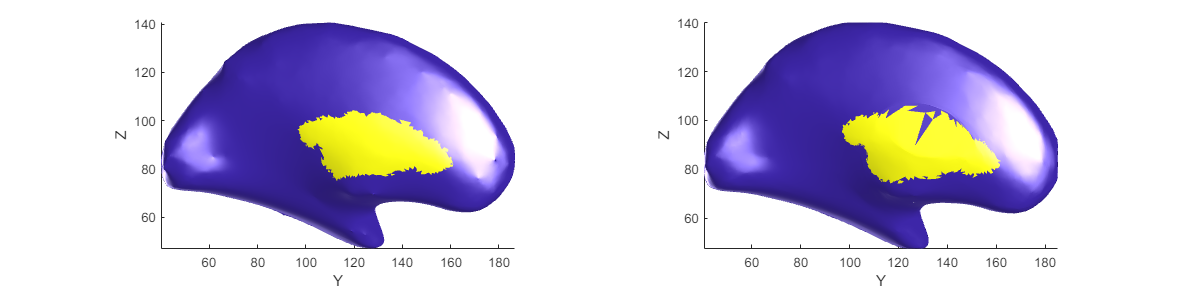

vregidxL_iswhite = surf_in.Labels;

figure;
next; plot_surf(mniL_sm3,'colors',vbinidxL_iswhite)
next; plot_surf(subjL_attachL,'colors',vregidxL_iswhite)
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view'); view(90,0)

surf_in = mniL_sm3;
square_ratio = 2;
mniL_square_corners = 80;
area_eps = 1e-5;

[surf_mniLdiv,~,idxL] = Surf_func_ROI(surf_in,'divide',vbinidxL_iswhite==0);
vmniL_idxL = idxL{2};

V = mniL_sph.Vertices(vmniL_idxL,:);
F = surf_mniLdiv{2}.Faces;
sph_mniLdiv = struct('Vertices',V,'Faces',F);
[mniL_flat,map_mniL] = Surf_func_GEO(sph_mniLdiv,'mapping_square','corners',mniL_square_corners,'area_eps',area_eps);

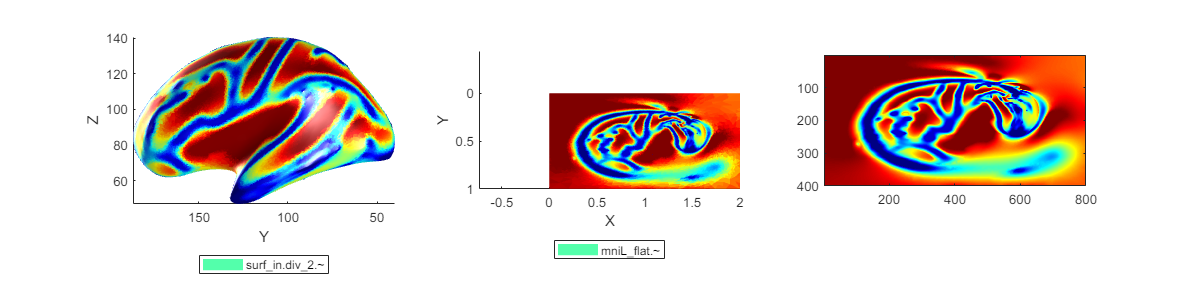

map_mniL_max = max(map_mniL,[],1);
map_mniL(:,1) = map_mniL(:,1)*square_ratio/map_mniL_max(1); map_mniL_max(1) = square_ratio;
mniL_flat.Vertices(:,[1,2]) = map_mniL;
mniLK3_div = mniLK3(vmniL_idxL); val = mniLK3_div;

texNy = 400;
texNx = round(texNy.*map_mniL_max(1));
func_interp_mniL = @(val) scatteredInterpolant_img(map_mniL,val,map_mniL_max([2,1]),[texNy,texNx]);
img_mniL_raw = func_interp_mniL(val); img_mniL = amp(img_mniL_raw);
imgX_mniL = func_interp_mniL(V(:,1)); imgY_mniL = func_interp_mniL(V(:,2)); imgZ_mniL = func_interp_mniL(V(:,3));
imgXYZ_mniL = cat(3,imgX_mniL,imgY_mniL,imgZ_mniL);

figure;
next; plot_surf(surf_mniLdiv{2},'colors',val); view(-90,0)
next; plot_surf(mniL_flat,'colors',val); lighting none; colormap jet; axis ij
next; showc(img_mniL)
lay_fig([12,3])

save([save_dir,'mniL_pialL_bin2_flat.mat'],'mniL_sph','vbinidxL_iswhite','vmniL_idxL','sph_mniLdiv', ...
    'mniL_square_corners','mniL_flat','img_mniL_raw','imgXYZ_mniL','mniLK1','mniLK2','mniLK3')

% subjL_file = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00004\surf\T1_reg.DL.right.inner.ply';
subjL_square_corners = 40;

v = surf_subjL.Vertices;
% v_idxL = (v(:,1)>93 & v(:,2)>80 & v(:,3)>58)>0;

surf_in = subjL_attachL;
[surf_div,~,idxL] = Surf_func_ROI(surf_in,'divide',vregidxL_iswhite==0); surf_div = surf_div{2};
vsubjL_idxL = idxL{2};

V = subjL_sphreg.Vertices(vsubjL_idxL,:); % !!!!! sphreg with sm
F = surf_div.Faces;
sph_subjLdiv = struct('Vertices',V,'Faces',F);
[subjL_flat,map_subjL] = Surf_func_GEO(sph_subjLdiv,'mapping_square','corners',subjL_square_corners,'area_eps',area_eps);
map_subjL(:,1) = square_ratio*map_subjL(:,1)/max(map_subjL(:,1));

% important
map_subjL = interp_sph(sph_mniLdiv.Vertices,map_mniL,sph_subjLdiv.Vertices);
subjL_flat.Vertices(:,[1,2]) = map_subjL;
subjLK3_div = subjLK3(vsubjL_idxL); val = subjLK3_div;

img_subjL_raw = scatteredInterpolant_img(map_subjL,val,map_mniL_max([2,1]),[texNy,texNx]);

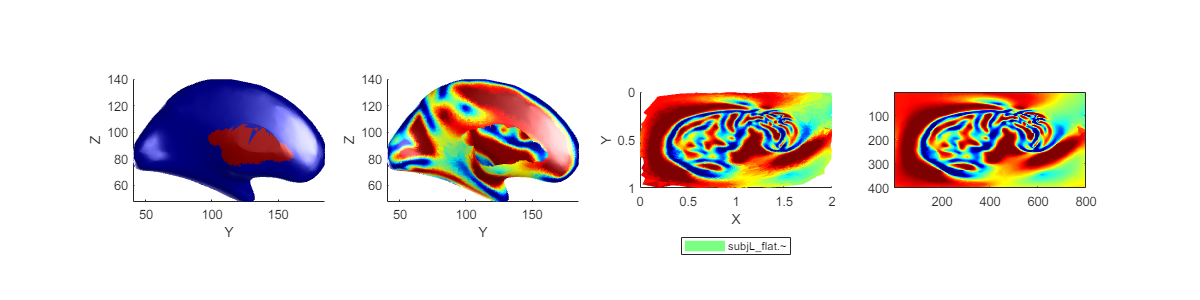

img_subjL = amp(img_subjL_raw);

figure; colormap jet
next; plot_surf(surf_in,'colors',double(vregidxL_iswhite));
next; plot_surf(surf_div,'colors',val); 
% next; plot_surf(subjL_sphreg,'colors',subjLK3);
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view'); view(90,0)
next; plot_surf(subjL_flat,'colors',val); lighting none; axis ij
next; showc(img_subjL)

save([save_dir,'mniL_pialL_bin2.mat'],'mniL_pialL_bin2','vidxL_iswhite','vbinidxL_iswhite','mniL_sm3','mniL_sph')

save([save_dir,'mniL_pialL_bin2_subjLreg.mat'],'subjL_sphreg','vsubjL_idxL','sph_subjLdiv','subjL_flat','subjL_file', ...
    'vregidxL_iswhite','img_subjL_raw','img_mniL_raw')

# use

load([save_dir,'mniL_pialL_bin2_flat.mat'])
load([save_dir,'mniL_pialL_bin2.mat'])
load([save_dir,'mniL_pialL_bin2_subjLreg.mat'])

square_ratio = 2;
mniL_square_corners = 80;
area_eps = 1e-5;
[mniL_flat,map_mniL] = Surf_func_GEO(sph_mniLdiv,'mapping_square','corners',mniL_square_corners,'area_eps',area_eps);

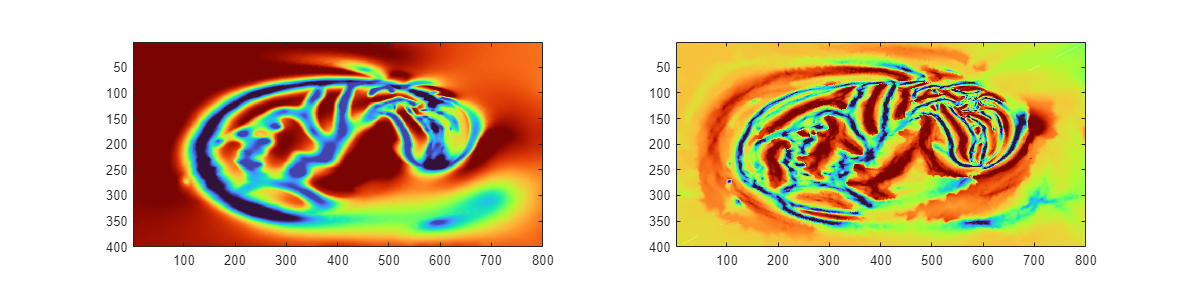

map_mniL_max = max(map_mniL,[],1);
texNy = 400;
texNx = 800;

func_interp_mniL = @(val) scatteredInterpolant_img(map_mniL,val,map_mniL_max([2,1]),[texNy,texNx]);

mniLK3_div = mniLK3(vmniL_idxL); val = mniLK3_div;
img_mniL_K3 = func_interp_mniL(val); 

mniLK1_div = mniLK1(vmniL_idxL); val = mniLK1_div;
img_mniL_K1 = func_interp_mniL(val);

figure; colormap turbo
next; showc(img_mniL_K3); next; showc(img_mniL_K1)
lay_fig([12,3])

save([save_dir,'mniL_pialL_bin2_subjLreg.mat'],'subjL_sphreg','vsubjL_idxL','sph_subjLdiv','subjL_flat','subjL_file', ...
    'vregidxL_iswhite','img_subjL_raw','img_mniL_raw','img_mniL_K1','img_mniL_K3')

function val_new = interp_sph(v,val_raw,v_q)
[TH,PHI] = cart2sph(v(:,1),v(:,2),v(:,3));
[TH_q,PHI_q] = cart2sph(v_q(:,1),v_q(:,2),v_q(:,3));

val_new = [];
for i = 1:2
    rot_TH = pi*(i-1);
    th = mod(TH+rot_TH,2*pi);
    th_q = mod(TH_q+rot_TH,2*pi);

    vv_in = [th,PHI];
    vv_q = [th_q,PHI_q];

    for j = 1:size(val_raw,2)
        interp_h = scatteredInterpolant(vv_in,val_raw(:,j));
        val_new(:,j,i) = interp_h(vv_q);
    end
end
w = 1 - abs(mod(TH_q,2*pi)/pi - 1);
w = permute(w,[1,3,2]);
val_new = val_new(:,:,1).*w + val_new(:,:,2).*(1-w);
end

function img = scatteredInterpolant_img(v,val,lim_max,img_sz)
x = linspace(0,lim_max(2),img_sz(2)); y = linspace(0,lim_max(1),img_sz(1));
[X,Y] = meshgrid(x,y);
interp_fmniL = scatteredInterpolant(v,val);
img = interp_fmniL([X(:),Y(:)]);
img = reshape(img,img_sz);
end